# APPLADE Declipping main 

This .mlx file is the main file to perform audio declipping with the proposed method, **APPLADE**.

close all
clear
clc

rng(0)

addpath(genpath("Training"))
addpath(genpath("Declipping"))
addpath(genpath("Dataset"))

## Load DNN parameters / Newly obtain DNN parameters

You can use the DNN parameters that was already trained and used in our experiments. Also, you can obtain DNN parametrs through training you modified. In the latter case, you first modify 'Training\Train_main.mlx' and then run it.

turnon = true;

if turnon
    load("Training/Trained_Networks/Trained/TrainedDNNParameters.mat");
else
    % 1. Modify 'Training\Train_main.mlx' as you want & run it.
    % 2. Insert the name of the folder and file, which contains the DNN
    %    parameters you obtained, to below.
    Filename = "hogehoge";
    load(["Training/Trained_Networks/",Filename]);
end

param.model = @(dlX) model(netParam, dlX); 

## Set Parameters

All the parameters are exactly the same as those explained in our paper.

param.wtype = 'hann';
param.w = 1024;
param.a = param.w/4;
param.M = param.w;
param.L = param.a*64; % about 1s & mod(shiftLen) = 0

param.maxit = 200;

param.inputSDR = [1 3 5 10 15];
N = length(param.inputSDR);

## Set DGT

**"DGTtool"** from [https://github.com/KoheiYatabe/DGTtool](https://github.com/KoheiYatabe/DGTtool) by Kohei Yatabe.

Please refer the URL above for detailed explanation of this toolbox.

F = DGTtool('windowShift',param.a,'windowLength',param.w,'FFTnum',param.M,'windowName','h');
F.makeWindowTight;

diffWin deleted
dual window checked


## Load Dataset

We use some audio files from **LibriSpeech **([https://www.openslr.org/12/](https://www.openslr.org/12/)), which is freely available under the very permissive CC BY 4.0 license ([https://creativecommons.org/licenses/by/4.0/deed.en](https://creativecommons.org/licenses/by/4.0/deed.en)).

You can substitute **any other datasets**, if you want. In that case, the argument of 'dir' below needs to be modified.

Sounds = dir('Dataset/Examples/*.flac');
NN = length(Sounds);
data = cell(NN,1);
info = audioinfo(Sounds(1).name);
param.Fs = info.SampleRate;
for n = 1:NN
    audio = audioread(Sounds(n).name);
    audio = audio/max(abs(audio));
    data{n} = voicedPartExtraction(audio, param);
end

## Initialize

Prep for the main loop. 

solution = cell(N,NN);

theta      = zeros(N,NN);
actualSDR  = zeros(N,NN);
percentage = zeros(N,NN);

deltaSDR         = NaN(N,NN);
deltaSDR_process = NaN(N,NN,param.maxit);

## Main

for nn = 1:NN
    
    sig = data{nn};
    calcSDR = @(result) sdr(sig, result);
    
    for n = 1:N
        
        [clip, param.idx, theta(n,nn), actualSDR(n,nn), percentage(n,nn)] = sdr2clip(sig, param.inputSDR(n));
        param.lambda = 30*percentage(n,nn)/100;
        
        [solution{n,nn}, deltaSDR_process(n,nn,:)] = main_APPLADE(sig, clip, param, F);

        deltaSDR(n,nn) = calcSDR(solution{n,nn}) - calcSDR(clip);
    end

end

index computed (OLA)


## Results

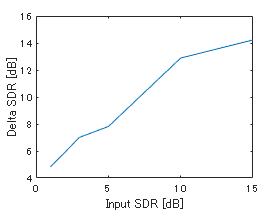

figure, plot(param.inputSDR, median(deltaSDR,2))
ylabel 'Delta SDR [dB]'
xlabel 'Input SDR [dB]'

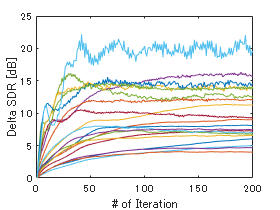


figure, plot(reshape(deltaSDR_process, [], param.maxit)')
ylabel 'Delta SDR [dB]'
xlabel '# of Iteration'